% Read the input image
path = getImgpath("field.jpg");
pathGT = getImgpathGT("fieldGT.tif");

% Read the input image
input_image = imread(path);
imgGT = imread(pathGT);
disp(size(imgGT));

        2048        2048



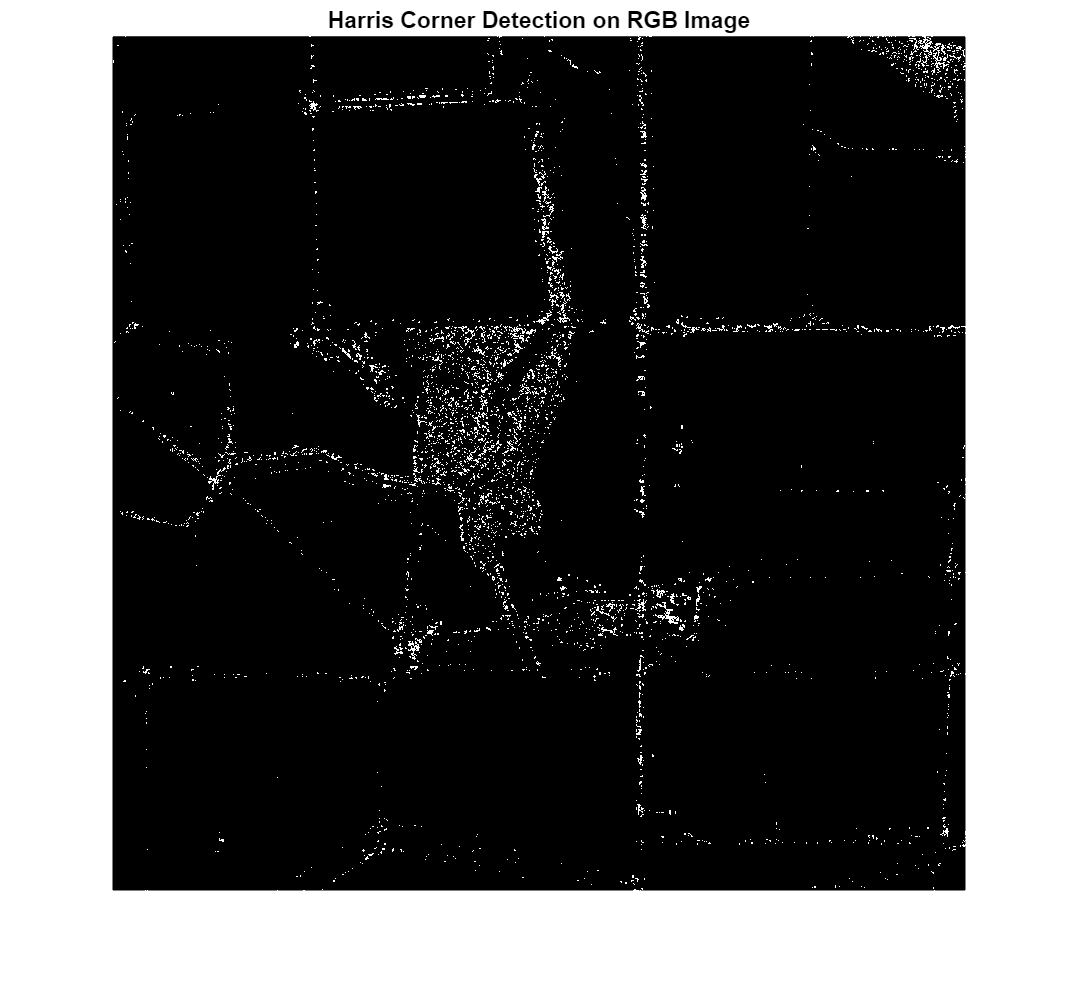

% Convert the input image to grayscale
gray_image = rgb2gray(input_image);

% Define Harris corner detection parameters
sigma = 1;  % Gaussian smoothing standard deviation
window_size = 3;  % Size of the window for the local neighborhood
k = 0.04;  % Harris corner constant

% Compute gradients of the image using Sobel operators
Ix = imfilter(double(gray_image), fspecial('sobel'), 'conv');
Iy = imfilter(double(gray_image), fspecial('sobel')', 'conv');

% Compute the elements of the Harris matrix
Ix2 = imfilter(Ix.^2, fspecial('gaussian', window_size, sigma), 'conv');
Iy2 = imfilter(Iy.^2, fspecial('gaussian', window_size, sigma), 'conv');
IxIy = imfilter(Ix .* Iy, fspecial('gaussian', window_size, sigma), 'conv');

% Calculate the Harris response
detM = Ix2 .* Iy2 - IxIy.^2;
traceM = Ix2 + Iy2;
harris_response = detM - k * traceM.^2;

% Threshold the Harris response to find corners
threshold = 0.001;  % Adjust this threshold as needed
corner_points = harris_response > threshold * max(harris_response(:));

% Get the coordinates of detected corner points
[r, c] = find(corner_points);

% Create an RGB image with black background
output_image = zeros(size(gray_image, 1), size(gray_image, 2), 3);

% Set the detected corner points to white
for i = 1:numel(r)
    output_image(r(i), c(i), :) = [255, 255, 255]; % White color for corners
end

% Draw lines connecting the corners (if needed)

% Display the RGB image with white corners on a black background
imshow(output_image);
title('Harris Corner Detection on RGB Image');

disp(size(output_image));

        2048        2048           3



disp(size(imgGT));

        2048        2048



IOUValue = findIOUAccuracy(output_image,imgGT);

Arrays have incompatible sizes for this operation.

Error in findIOUAccuracy (line 8)
    intersection = sum(imgGT(:) & img(:));

Related documentation

fprintf("IOU Value %f\n", IOUValue);
output_image = im2single(output_image);

% Calculate SSIM accuracy
ssimval = ssim(output_image, single(imgGT)) * 100;
fprintf("SSIM Accuracy is %f\n", ssimval);
